close all; clearvars; clc;

## 1. Generate Data Set trainning from the pdf Gaussian mixture model.

Descomentar una de las líneas para cambiar los parámetros reales del data set (1 dimensión, 1 clase) generado a partr de una fdp multimodal

ejemp='1'; 
%ejemp='2';
%ejemp=3;
%ejemp=4;
%ejemp=5;
%ejemp=6;
%ejemp=7;

switch ejemp
    case '1'
        m=[0; 2]';
        S(:,:,1)=[0.2];
        S(:,:,2)=[0.2];
        P=[1/3 2/3];
        N=1000;
        h=0.1;
    case '2'
        m=[0; 2]';
        S(:,:,1)=[0.2];
        S(:,:,2)=[0.2];
        P=[1/3 2/3];
        N=200;
        h=0.1;
    case '3'
        m=[0; 2]';
        S(:,:,1)=[0.2];
        S(:,:,2)=[0.2];
        P=[1/3 2/3];
        N=10000;
        h=0.1;
    case '4'
        m=[0; 2]';
        S(:,:,1)=[0.2];
        S(:,:,2)=[0.2];
        P=[1/3 2/3];
        N=1000;
        h=0.01;
    case '5'
        m=[0; 2]';
        S(:,:,1)=[0.2];
        S(:,:,2)=[0.2];
        P=[1/3 2/3];
        N=10000;
        h=0.01;        
        
    case '6'
        m=[1.4; 3.2]';
        S(:,:,1)=[0.3];
        S(:,:,2)=[0.6];
        P=[1/3 2/3];
        N=2000;
        h=0.1;
        
    case '7' 
        m=[0; 4]';
        S(:,:,1)=[0.3];
        S(:,:,2)=[0.2];
        P=[1/4 3/4];
        N=3000;
        h=0.1;
end 

randn('seed',0);
[X]=generate_gauss_classes(m,S,P,N);

## Plot the training data set

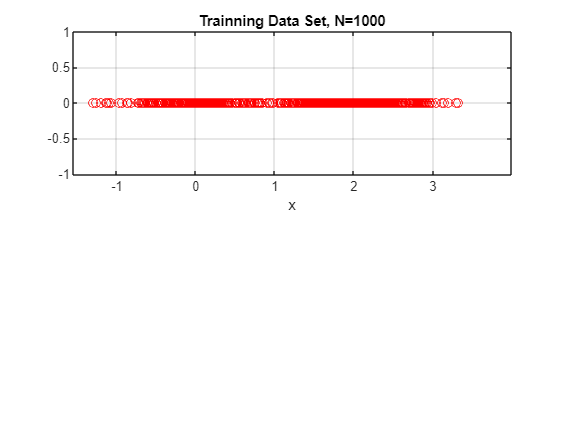

subplot(2,1,1); plot(X, 0, 'ro'); xlabel('x');title(['Trainning Data Set, N=' num2str(N)]);

xmin=min(X);xmax=max(X);
axis([ 1.2*xmin  1.2*xmax   -1 1 ] );grid on;

## Plot the pdf

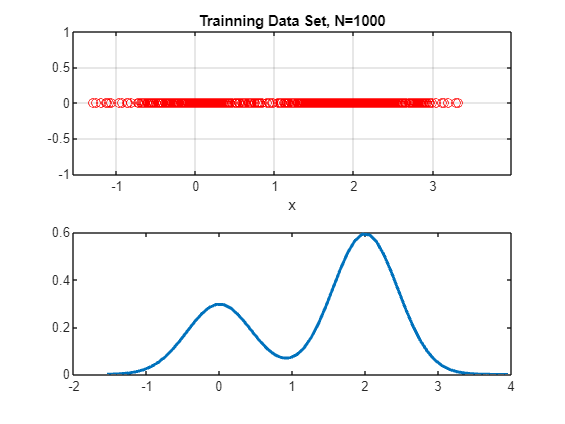

Current plot held


x=1.2*xmin:0.1:1.2*xmax;
pdfx=P(1)*(1/sqrt(2*pi*S(:,:,1)))*exp(-.5*((x-m(1)).^2)/S(:,:,1))+ P(2)*(1/sqrt(2*pi*S(:,:,2)))*exp(-.5*((x-m(2)).^2)/S(:,:,2));
subplot(2,1,2);
plot(x,pdfx, 'LineWidth',2); hold;

## 2. Compute and plot the approximation of the pdf (for h ) by Window

## Parzen Method

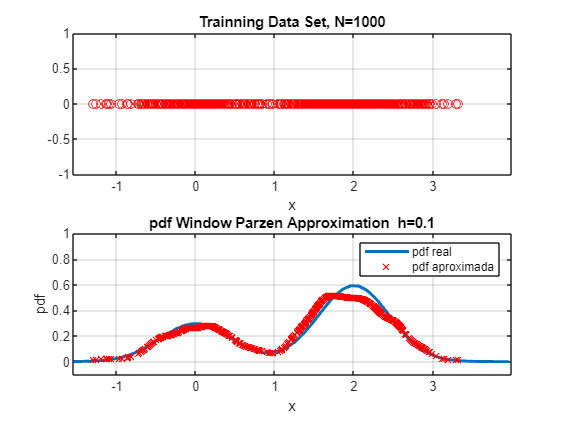

pdfx_approx=CalculParzen_gauss_kernel(X,h);
plot(X,pdfx_approx,'xr'); grid on; xlabel('x'); ylabel('pdf')
axis([ 1.2*xmin  1.2*xmax   -0.1 1 ] ); title(['pdf Window Parzen Approximation  h=' num2str(h)])
legend('pdf real', 'pdf aproximada')